**Estrazione degli outliers usando ResNet50**

Classe: 0, Immagini analizzate: 50 su 549
Classe: 0, Immagini analizzate: 100 su 549
Classe: 0, Immagini analizzate: 150 su 549
Classe: 0, Immagini analizzate: 200 su 549
Classe: 0, Immagini analizzate: 250 su 549
Classe: 0, Immagini analizzate: 300 su 549
Classe: 0, Immagini analizzate: 350 su 549
Classe: 0, Immagini analizzate: 400 su 549
Classe: 0, Immagini analizzate: 450 su 549
Classe: 0, Immagini analizzate: 500 su 549


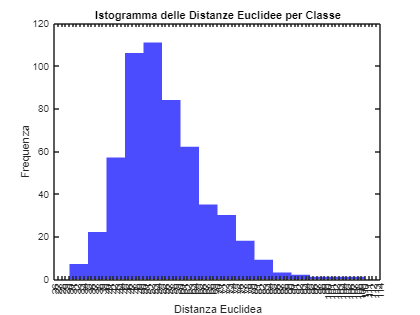

   64.0485



Error using copyfile
The location 'C:\Users\nada2\Desktop\visual_proj\outliers_treshold80\train_103684.jpg' was not found.

% Rete neurale preaddestrata ResNet50
net = resnet50;

% Percorso del tuo dataset
datasetPath = '../visual_proj/train_set';

% File CSV che contiene le associazioni tra immagini e classi
csvFilePath = '../visual_proj/train_info_dirty.csv';
csvData = readtable(csvFilePath);


uniqueClasses = num2cell(unique(csvData{:, 2}));

% Percorso di salvataggio delle liste
outputPath = '../visual_proj/outliers_treshold80/';

% Ciclo sulle classi
for classIndex = 1:length(uniqueClasses)
    currentClass = uniqueClasses{classIndex};


    % CSV per la classe corrente (filtro)
    classData = csvData(csvData{:, 2} == currentClass, :);


    if ~isempty(classData)

        imageList = [];
        featureList = [];
        imageNameList = {};

        % Ciclo sulle immagini della classe corrente
        for fileIndex = 1:size(classData, 1)
            imagePathCell = fullfile(datasetPath, [classData{fileIndex, 1}]);

            if mod(fileIndex, 50) == 0
                disp(['Classe: ', num2str(currentClass), ', Immagini analizzate: ', num2str(fileIndex), ' su ', num2str(size(classData, 1))]);
            end

            imagePath = imagePathCell{1};
            

            img = imread(imagePath);

            img = imresize(img, [224, 224]);

            % Estrazione feature con ResNet50
            features = activations(net, img, 'fc1000', 'OutputAs', 'rows');

            imageList = [imageList; img];
            featureList = [featureList; features];

            imageNameList{end+1} = classData{fileIndex, 1};
        end
        
        % inizio ora ad identificare gli outliers all'interno della classe
        % considerata

        % Calcolo le distanze euclidee per ciascuna immagine nella classe
        distancesByClass = zeros(size(featureList, 1), 1);
        classMean = mean(featureList, 1);
        
        for i = 1:size(featureList, 1)
            distancesByClass(i) = sqrt(sum((featureList(i, :) - classMean).^2));
        end

        % Visualizzazione dell'istogramma con etichette delle classi
        h = histogram(distancesByClass, 'BinMethod', 'auto', 'EdgeColor', 'none', 'FaceColor', 'b', 'FaceAlpha', 0.7);
        
        classLabelsNumeric = 1:length(uniqueClasses);
        classLabelsCell = cellfun(@num2str, num2cell(classLabelsNumeric), 'UniformOutput', false);
        
        h.Parent.XTick = classLabelsNumeric;
        h.Parent.XTickLabel = classLabelsCell;
        
        xlabel('Distanza Euclidea');
        ylabel('Frequenza');
        title('Istogramma delle Distanze Euclidee per Classe');

      
        % provo ad escludere il 20%
        threshold = prctile(distancesByClass, 80);

        disp(threshold)

        % Trovo gli outlier utilizzando la soglia
        outlierIdx = distancesByClass > threshold;


        outlierImages = imageList(outlierIdx, :, :, :);
        outlierImageNames = imageNameList(outlierIdx);
        
        % Percorso del salvataggio delle immagini outlier 
        outlierSavePath = '../visual_proj/outliers_treshold80';



        % Salvataggio degli outlier nella cartella specificata in
        % precedenza
        for j = 1:size(outlierImages, 1)
            fileName = [outlierImageNames{j}];
            demoTrainFilePath = fullfile('../visual_proj/train_set', fileName{1});

            outlierSaveFilePath = fullfile(outlierSavePath, fileName{1});
            
            copyfile(demoTrainFilePath, outlierSaveFilePath);
        end
        

        % Creazione del CSV degli outliers
        demoTrainData = readtable('../visual_proj/train_info_dirty.csv');
        
        allImageNames = demoTrainData.Var1;
        allClasses = demoTrainData.Var2;
        
        outlierIdx = any(distancesByClass > threshold, 2);
        
        outlierImages = imageList(outlierIdx, :, :, :);
        outlierImageNames = imageNameList(outlierIdx);
        outlierClasses = allClasses(outlierIdx);

        if classIndex == 1
            csvSavePath = '../visual_proj/outliers_treshold80/outliers_treshold80.csv';
        
            outlierTable = table(outlierImageNames', outlierClasses, 'VariableNames', {'ImageName', 'Class'});
            
            % File CSV
            writetable(outlierTable, csvSavePath);

        else
            x = readtable(csvSavePath);
            outlierTable2 = table(outlierImageNames', outlierClasses, 'VariableNames', {'ImageName', 'Class'});
            merge_table = vertcat(x, outlierTable2);
            
            writetable(merge_table, csvSavePath);
        end           
          

        % Clear delle variabili
        clear imageList featureList imageNameList;
    end
end